Code Adapted from

Al-Khazzar, Akram. (2015). A comprehensive solar angles simulation and calculation using Matlab. INTERNATIONAL JOURNAL OF ENERGY AND ENVIRONMENT. 6. 367-376. 

[https://www.researchgate.net/publication/283051726_A_comprehensive_solar_angles_simulation_and_calculation_using_Matlab](https://www.researchgate.net/publication/283051726_A_comprehensive_solar_angles_simulation_and_calculation_using_Matlab)

clear, clc
altitude_figure = figure(); %creates a blank altitude figure
azimuth_figure = figure(); %creates a blank azimuth figure
% Variable of interest to feed into Simulink
stored_times = [];
stored_sun_altitude = [];
stored_sun_azimuth = [];

Month Data

days_in_month = [31 28 31 30 31 30 31 31 30 31 30 31];
m=[0 31 59 90 120 151 181 212 243 273 304 334]; %days passed at after each month of the year

General Date and Positional Information

month = 1:12;  % inset a month number from 1 to 12
% month = [6 12];

day = 21; %insert the sequence of the day in the month, from 1 to 31
L =-28.4508*pi/180; %latitude for uppington (in radians)

Main Code:

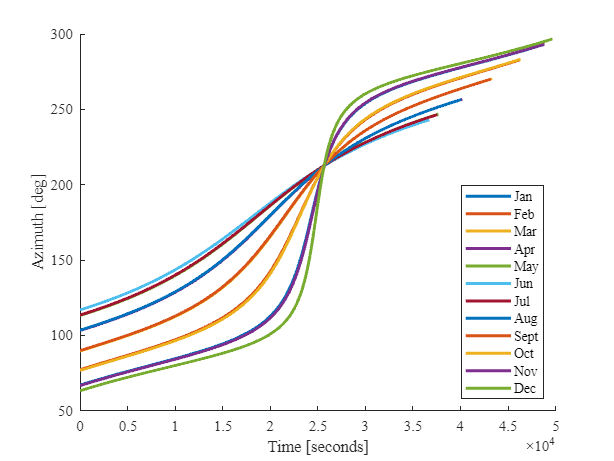

for x = month  
    counter = 1;
    
    n=m(x)+day; %this step evaluate the day sequence number in the year
    
    declination_angle=23.45*sin(360*(284+n)/365*pi/180); %see equ(1)
    d= declination_angle*pi/180; %conversion to radians

    for hour = 0:23 %corrseponding to 24 hours in a day
        for minute = 0:59 % corresponding to 60 minutes in an hour
            altitude_angle = calculateAltitudeAngle(d, L, hour, minute);
            sun_data_altitude(counter) = altitude_angle;
            sun_data_azimuth(counter) = calculateAzimuthAngle(d, hour, minute, altitude_angle*pi/180);
            minute_data(counter) = counter; %corresponds to each minute of every hour for a full day
            counter = counter + 1;
        end
    end

    altitude_range = plotAltitude(minute_data, sun_data_altitude, altitude_figure); %plotting altitude graph
    [dt, da] = plotAzimuth(altitude_range, minute_data, sun_data_azimuth, azimuth_figure); %plotting azimuth graph

    if x == 6
        jun_time = dt;
        jun_azimuth = da;
        jun_altitude = sun_data_altitude(altitude_range(1):altitude_range(2))*pi/180;
    else
        dec_time = dt;
        dec_azimuth = da;
        dec_altitude = sun_data_altitude(altitude_range(1):altitude_range(2))*pi/180;
    end
end


jun_time = jun_time(1:6:end);
jun_azimuth = jun_azimuth(1:6:end);
jun_altitude = jun_altitude(1:6:end)';

dec_time = dec_time(1:6:end);
dec_azimuth = dec_azimuth(1:6:end);
dec_altitude = dec_altitude(1:6:end)';

% disp("june")

june


% jun_azimuth(1)*180/pi

ans =      1.168665071679793e+02


% jun_azimuth(end)*180/pi

ans =      2.431334928320207e+02


% jun_altitude(1)*180/pi

ans =   -0.073519460935572


% jun_altitude(end)*180/pi

ans =   -0.073519460935593


% 
% disp("december")

december


% dec_azimuth(1)*180/pi

ans =   63.133492832020707


% dec_azimuth(end)*180/pi

ans =      2.968665071679793e+02


% dec_altitude(1)*180/pi

ans =    0.073519460935588


% dec_altitude(end)*180/pi

ans =    0.073519460935599


function Altitude_angle = calculateAltitudeAngle(d, L, hour, min)
    hour_angle=((hour+min/60)-12)*15; %see equ(2)
    h=hour_angle*pi/180;
    Altitude_angle = asin(sin(L)*sin(d)+cos(L)*cos(d)*cos(h))*180/pi; %see equ(3) - degree value
end

function Azimuth_angle = calculateAzimuthAngle(d, hour, min, a)
    hour_angle=((hour+min/60)-12)*15; %see equ(2)
    h=hour_angle*pi/180; %radian value
    Azimuth_angle=asin(cos(d)*sin(h)/cos(a))*180/pi; %see equ(4) - degree value
end

function limit = plotAltitude(minute_data, sun_data_altitude, plot_1)
%%%%%%%%%%Fixing the altitude range to be a parabola from 0 - 0%%%%%%%%%%%%
    abs_sd = abs(sun_data_altitude);
    cutOff = length(abs_sd)/2;

    altLowerLimit = find(abs_sd(1:cutOff) == min(abs_sd(1:cutOff)), 1, 'first');
    altUpperLimit = find(abs_sd(cutOff+1:end) == min(abs_sd(cutOff+1:end)), 1, 'last') + cutOff;
    altitude_range = [altLowerLimit altUpperLimit];

    sun_data_altitude_fixed_range = sun_data_altitude(altLowerLimit:altUpperLimit);
    minute_data_fixed_range = minute_data(altLowerLimit:altUpperLimit);
    limit = altitude_range; %sets the limit for the azimuth graph to be the same as the altitude
end

function [dt, da] = plotAzimuth(altitude_range, minute_data, sun_data_azimuth, plot_2)
%%%%%%%%%%%%%%%%%%%%%%%%%Fixing Azmuth Data%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    azLowerLimit = find(sun_data_azimuth == min(sun_data_azimuth));
    azUpperLimit = find(sun_data_azimuth == max(sun_data_azimuth));

    lower_data = -180 - sun_data_azimuth(1:azLowerLimit);
    upper_data = 180 - sun_data_azimuth(azUpperLimit:end);
    middle_data = sun_data_azimuth(azLowerLimit + 1: azUpperLimit-1);

    sun_data_azimuth_fixed = [lower_data, middle_data, upper_data];
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Plotting the azimuth data for daylight hours only:

    sun_data_azimuth_fixed_range = (sun_data_azimuth_fixed(altitude_range(1):altitude_range(2))+180);
    minute_data_fixed_range = (minute_data(altitude_range(1):altitude_range(2)) - minute_data(altitude_range(1))).*60;

    hold on
    plot(minute_data_fixed_range, sun_data_azimuth_fixed_range, LineWidth=2)
    fontname("Times New Roman", 11)
    % title("Azimuth Angle Throughout the 21st Day of the Month")
    xlabel("Time [seconds]")
    ylabel("Azimuth [deg]")
    % legend("Winter Solstice (Jun)", "Summer Solstice (Dec)", location="southeast")
    legend("Jan", "Feb","Mar","Apr","May","Jun", "Jul", "Aug", "Sept", "Oct", "Nov", "Dec", location="southeast")
    hold off

    da = (sun_data_azimuth_fixed_range.*pi/180)';
    dt = minute_data_fixed_range';
end